# Compressed air storage results

This is the analysis of the results of the compressed air energy storage

load CA_final.mat

d_long.HourDK(1)+years(30)

ans = datetime
   2050-10-01T06:36:00


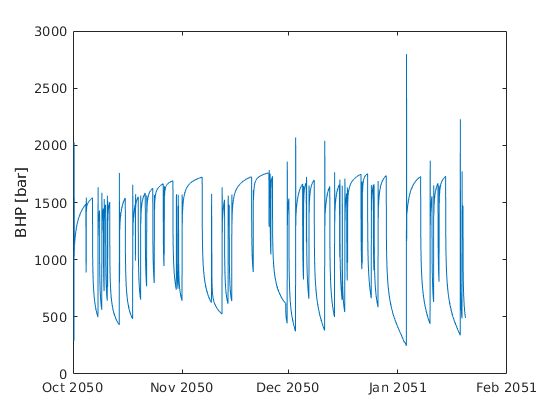

figure(5)
plot(d_long.HourDK(1:end-1)+years(30), p_hist/1e5)
axis normal
ylabel('BHP [bar]')
saveas(gcf, 'CA_p_hist.jpg')

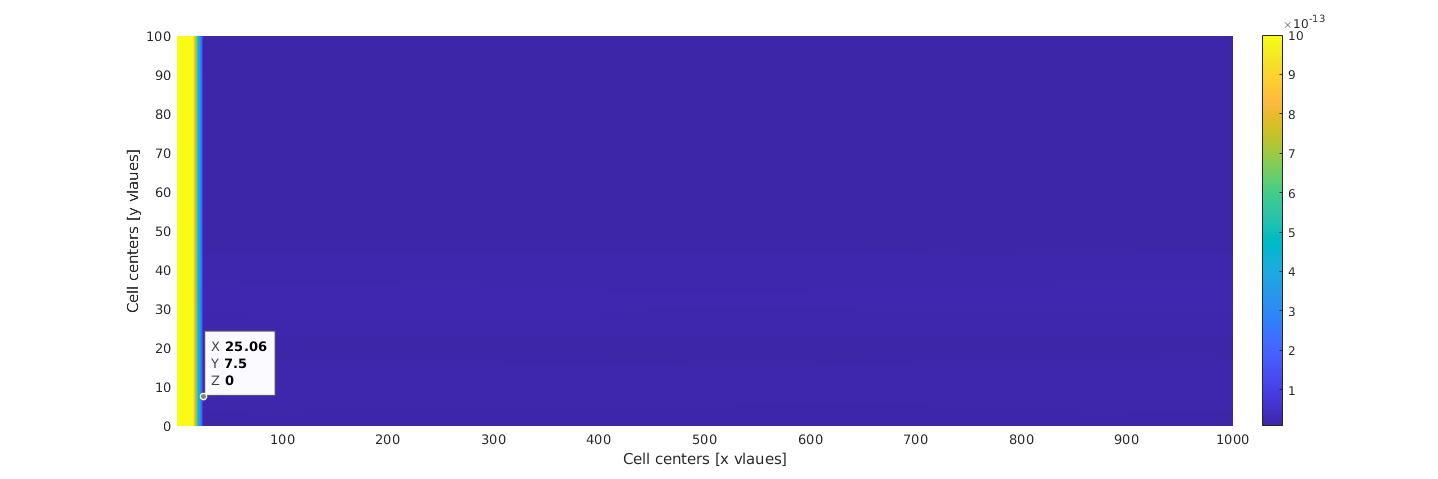

hFig = figure(2);
set(hFig, 'Position', [200 200 1500 500]);
visualizeCells(k); axis normal; shading interp;
saveas(gcf, 'CA_perm_harald.jpg')

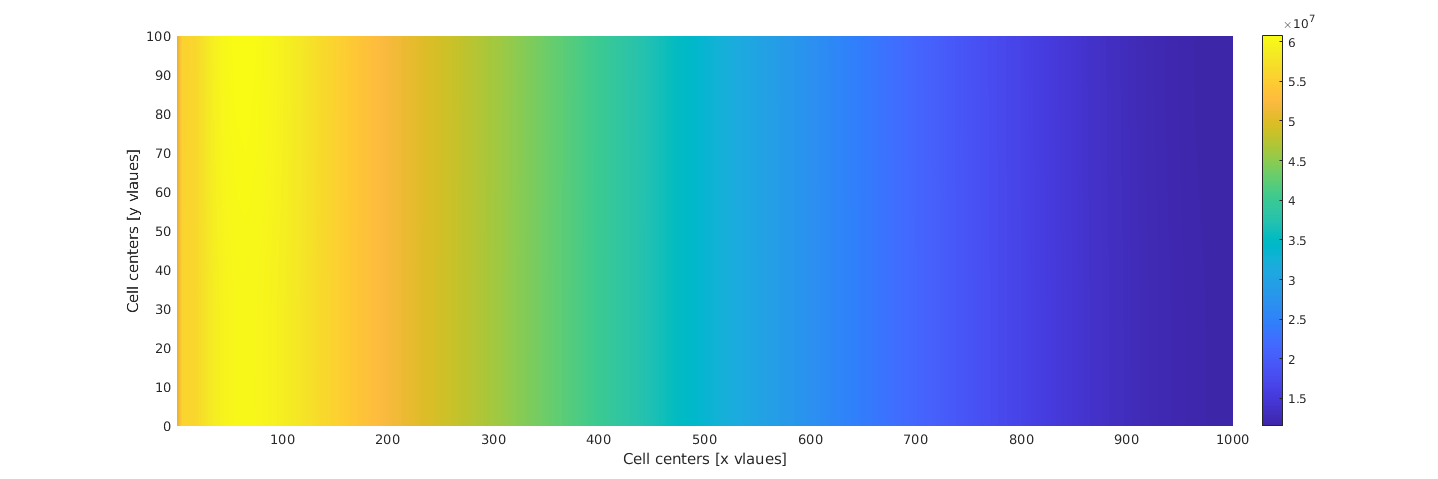

hFig = figure(3);
set(hFig, 'Position', [200 200 1500 500]);
visualizeCells(p_val); shading interp; axis normal;
saveas(gcf, 'CA_pressure_harald.jpg')

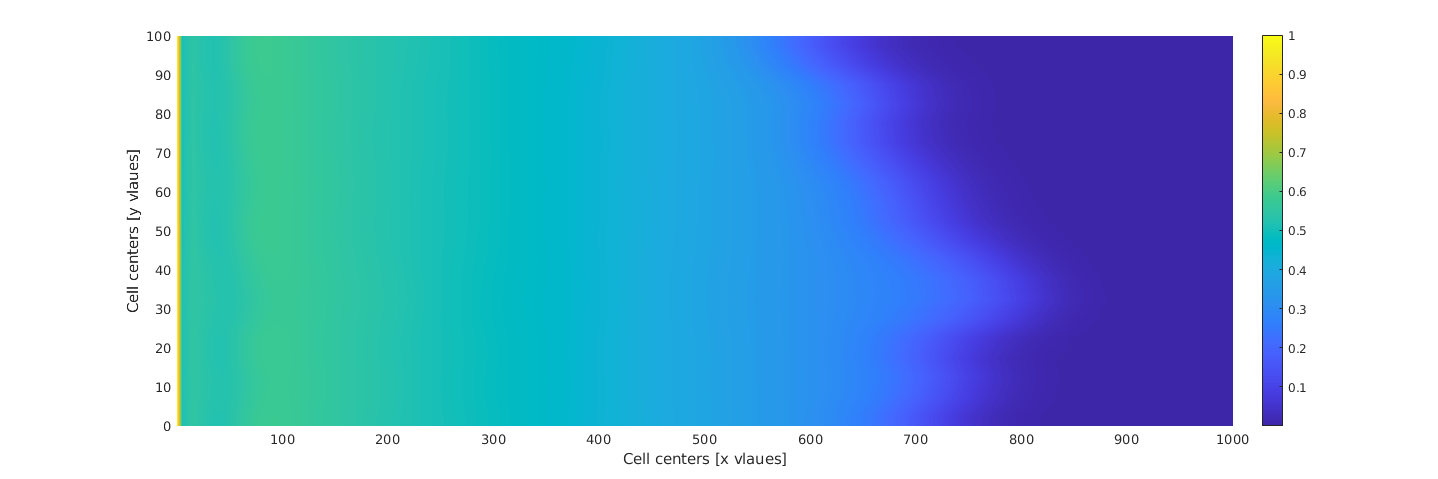

hFig = figure(4);
set(hFig, 'Position', [200 200 1500 500]);
visualizeCells(c_init); shading interp; axis normal;
saveas(gcf, 'CA_tracer_harald.jpg')

consumed_elec = sum((m_hist>0)*elec_max/1e6) % MWh

consumed_elec = 29360

% w_isentropic = compressor_station(p_atm, p_inj, comp_ratio, comp, T_inj);
produced_elec = 0;
for i=1:length(p_hist)
    if m_hist(i)<0
        produced_elec = produced_elec+m_hist(i)*eta_turbine*exergy(p_hist(i), T_ref, 'Air');
    end
end
produced_elec = -produced_elec/1e6

produced_elec = 459.4757

eff = produced_elec/consumed_elec

eff = 0.0156